close all;
clear all;
A=xlsread('tension_middle_1.csv');
B=xlsread('tension_sides_1.csv');
C=xlsread('compresion_middle_1.csv');
D=xlsread('compression_side_1.csv');
color.code=colormap(slanCM(160));

@author : slandarer


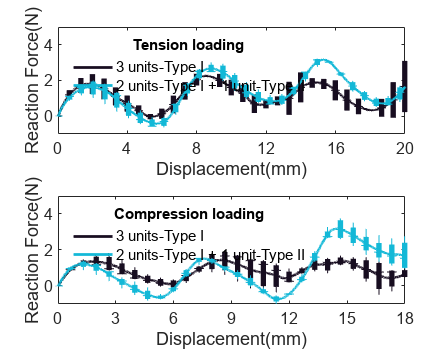

color.l=length(color.code);
color.index1=round(color.l*1/9);
color.index2=round(color.l*7/9);
figure('DefaultAxesFontSize',14,'Position',[200 200 800 640]);
%newcolors= {'#CD84F1', '#FFCCCC', '#FF4D4D', '#FFAF40', '#2F3542', '#FFFA65'};
%newcolors2=hex2rgb(newcolors);
%colororder(newcolors2);
subplot(2,1,1)
[yave1,dave1,Y1,pos1]=data_ave_and_bocplot(A);
boxplot(Y1,'positions',pos1,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'OutlierSize',14);
hold on
plot(dave1,yave1,'LineWidth',2,'Color',color.code(color.index1,:));
[yave2,dave2,Y2,pos2]=data_ave_and_bocplot(B);
boxplot(Y2,'positions',pos2,'Colors',color.code(color.index2,:),'BoxStyle','filled','Widths',0.5,'OutlierSize',14);
hold on
plot(dave2,yave2,'LineWidth',2,'Color',color.code(color.index2,:));
axis([0 20 -1 5]);
xticks(0:4:20);
xticklabels({'0','4','8','12','16','20'});
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
lgd1=legend('3 units-Type I','2 units-Type I + 1 unit-Type II');
title(lgd1,'Tension loading');
legend('boxoff');
legend('Location','northwest','FontName','Arial');
ax=gca;
ax.FontName='Arial';


subplot(2,1,2)
[yave3,dave3,Y3,pos3]=data_ave_and_bocplot(C);
boxplot(Y3,'positions',pos3,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'OutlierSize',14);
hold on
plot(dave3,yave3,'LineWidth',2,'Color',color.code(color.index1,:));
[yave4,dave4,Y4,pos4]=data_ave_and_bocplot(D);
boxplot(Y4,'positions',pos4,'Colors',color.code(color.index2,:),'BoxStyle','filled','Widths',0.5,'OutlierSize',14);
hold on
plot(dave4,yave4,'LineWidth',2,'Color',color.code(color.index2,:));
axis([0 18 -1 5]);
xticks(0:3:18);
xticklabels({'0','3','6','9','12','15','18'});
lgd2=legend('3 units-Type I','2 units-Type I + 1 unit-Type II');
title(lgd2,'Compression loading');
legend('boxoff');
legend('Location','northwest','FontName','Arial');
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
ax=gca;
ax.FontName='Arial';